clear all; close all; clc; rng(1);

## Function to be learned

y0     = zeros(2, 1);
y_next = @(y, u) [ ...
                     0.8 * y(1) + sin(pi * u(1)) + 0.5 * u(2);
                     0.6 * y(2) + cos(pi * u(2)) + 0.5 * u(1);
                 ];

u = [linspace(-2, 2, 50); linspace(-2, 2, 50)];

## Neural Network Architecture

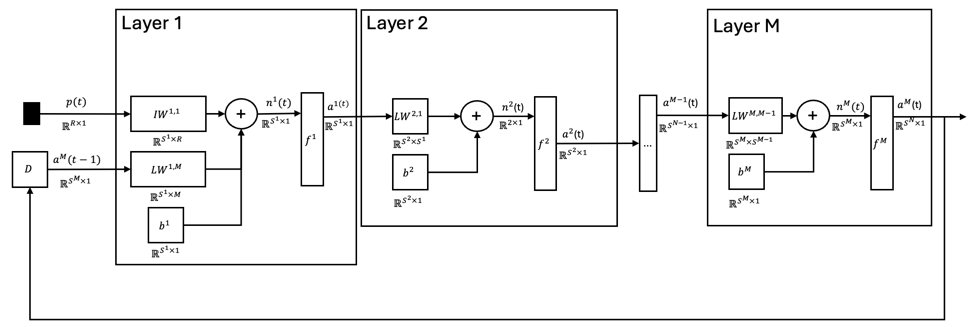

f  = {
        @(n) logsig(n)
        @(n) purelin(n)
     };
df = {
        @(n) logsig(n) .* (1 - logsig(n))
        @(n) ones(size(n))
     };

trainingData = twodi_TrainingData_Class();

y(:, 1) = y0;
for i = 2 : 1 : size(u, 2), y(:, i) = y_next(y(:, i - 1), u(:, i));                              end
for i = 1 : 1 : size(u, 2), trainingData.addTrainingSample("input", u(:, i), "output", y(:, i)); end

**Visualize the data**

t = zeros(2, trainingData.getNrOfTrainingSamples());
p_plot = zeros(2, trainingData.getNrOfTrainingSamples());

for q = 1:trainingData.getNrOfTrainingSamples()

    [p_q, t_q] = trainingData.getTrainingSample(q);

    p_plot(:, q) = p_q;
    t(:, q)      = t_q;

end

figure('Position', [100 100 900 600]);
subplot(2,2,1); plot(1:size(p_plot,2), p_plot(1,:), 'LineWidth',1.5); grid on; xlabel('Sample q'); title('p_{1,q}');
subplot(2,2,2); plot(1:size(t,2),      t(1,:),      'LineWidth',1.5); grid on; xlabel('Sample q'); title('t_{1,q}');
subplot(2,2,3); plot(1:size(p_plot,2), p_plot(2,:), 'LineWidth',1.5); grid on; xlabel('Sample q'); title('p_{2,q}');
subplot(2,2,4); plot(1:size(t,2),      t(2,:),      'LineWidth',1.5); grid on; xlabel('Sample q'); title('t_{2,q}');

$F\left(\mathbb{x}\right)=\beta {\mathbb{v}}^T \mathbb{v}+\alpha {\mathbb{x}}^T \mathbb{x}$** instead of **$F\left(\mathbb{x}\right)={\mathbb{v}}^T \mathbb{v}$

Q = trainingData.getNrOfTrainingSamples();

NR_OF_EPOCHS = 1e5;

alpha = 0.01;

h = waitbar(0, 'Training progress...');
ITER = struct([]);
for epoch = 1 : 1 : NR_OF_EPOCHS

    ITER(epoch).network = twodi_NetworkLRMLP_Class(                       ...
                                                   "nrOfLayers" , 2     , ...
                                                   "nrOfInputs" , 2     , ...
                                                   "nrOfNeurons", [8, 2], ...
                                                   "actvnFcn"   , f     , ...
                                                   "dActvnFcn"  , df      ...
                                                );
    if(epoch >= 2)
        ITER(epoch).network.setPrms(ITER(epoch - 1).network.getPrms);
    end

    M     = ITER(epoch).network.getNrOfLayers;

            **Compute the derivate of the cost function **$F=\sum_{t=1}^Q {e\left(t\right)}^T e\left(t\right)$

    dF_dx = zeros(1, ITER(epoch).network.getNrOfPrms);
    for q = 1 : 1 : Q

        [p_q, t_q] = trainingData.getTrainingSample(q);
        [n, a]     = ITER(epoch).network.evaluate(p_q);
        daM_dx     = ITER(epoch).network.fwdSnvty_daM_dx(p_q);
        dF_daM     = ITER(epoch).network.backwSnvty_dF_daM(t_q);

        dF_dx = dF_dx + (dF_daM * daM_dx);

    end
    dF_dx = dF_dx / Q;

          **  Batch steepest descent**

    x_new = ITER(epoch).network.getPrms - alpha * dF_dx';

    ITER(epoch).network.setPrms(x_new);

            **Update progress bar**

    waitbar(epoch / NR_OF_EPOCHS, h, sprintf('Training progress: %.1f%%', 100 * epoch / NR_OF_EPOCHS));
end
close(h);

## Validation

NR_OF_FRAMES = 50;

t_target = zeros(2, Q);

for q = 1:Q
    [~, t_q] = trainingData.getTrainingSample(q);
    t_target(:,q) = t_q;
end

figure('Position',[100 100 900 600]);

subplot(2,1,1);
plot(1:Q, t_target(1,:), 'k-', 'LineWidth',2); hold on;
h1 = plot(1:Q, nan(1,Q), 'r--', 'LineWidth',2);
grid on;
xlabel('Sample q');
ylabel('Output 1');
legend({'Target','Neural network'}, 'Location','best');

subplot(2,1,2);
plot(1:Q, t_target(2,:), 'k-', 'LineWidth',2); hold on;
h2 = plot(1:Q, nan(1,Q), 'r--', 'LineWidth',2);
grid on;
xlabel('Sample q');
ylabel('Output 2');
legend({'Target','Neural network'}, 'Location','best');

for epoch = round(linspace(1, NR_OF_EPOCHS, NR_OF_FRAMES))

    network = ITER(epoch).network;
    y_hat   = zeros(2,Q);

    for q = 1:Q

        [p_q, ~] = trainingData.getTrainingSample(q);
        [~, a]   = network.evaluate(p_q);

        y_hat(:,q) = a{end}{end};

    end

    set(h1, 'YData', y_hat(1,:));
    set(h2, 'YData', y_hat(2,:));

    sgtitle(sprintf('Dynamic approximation - Epoch %d', epoch));

    drawnow;
    pause(0.1);

end